# Maximizing Solar Panel Output for a Fixed Area

In this project, our team **Solar Panel Team #3** designed a solution to identify the **optimal tilt angle** and **optimal aspect ratio** of a solar panel to deliver the **maximal energy output** given environmental constraints. Additionally this project maps the optimal energy output onto a surf plot to illustrate how energy output is dependent on tilt angle and aspect ratio. 

## MODEL 2: Scalable Constraints 

The purpose of this model is to find the maximum energy output when constraints can be varied. This allows for greater flexibility and practicality. 

### Objective 1: Implement the Optimization Problem

The [optimization problem](https://www.mathworks.com/help/releases/R2026a/optim/ug/problem-based-workflow.html) solves for the **Maximum Energy Output**. 

% Step 1: Define the Optimization Problem (Solar_Max). Give it a description of its purpose and solve for Maximum Value Output
    Solar_Max = optimproblem("Description","The Maximal Energy Output","ObjectiveSense","maximize");

By defining the optimization variables **Tilt Angle **(theta) and **Aspect Ratio **(r), the solver finds the highest energy output given the varying constraints of Tilt Angle and Aspect Ratio. 

In Model 2, the environmental **Constraints are Scalable.** This provides a more practical usage of how to optimize for Maximum Energy Output.

Utilizing the [control panel](https://www.mathworks.com/help/matlab/matlab_prog/add-interactive-controls-to-a-live-script.html), sliders will be used to set the upper and lower bounds of each optimization variable. 

- Absolute Min & Max limit for Tilt Angle ($\theta$) using slider: $0\degree \le \theta \le 180\degree$ (this can be changed by right clicking on the slider and pressing 'Configure Control')

- Absolute Min & Max limit of Aspect Ratio (r) using slider: $0\le r\le 10$ (can be changed the same way as above)

Where to find the Control Panel:

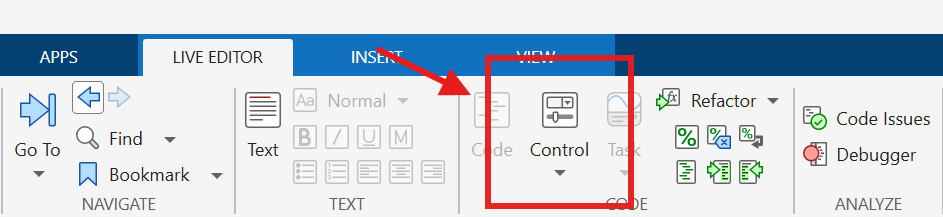

Note: The Upperbound Slider value cannot be lower then the Lowerbound slider value otherwise the **Code Will Not Run**

% Step 2: Using the control panel, create two sliders for each optimization variable representing the upper and lower bounds respectively
    % Note: In the control panel set "Run" to 'All Sections', do this for
    % all sliders 
        
    % For Tilt Angle (theta):
        % Define the LowerBound "theta_LowerB" and the UpperBound 
        % "theta_UpperB". Both sliders will span from 0 to 180 with a step
        % of 1 
        theta_LowerB = 90;
        theta_UpperB = 180;
    % For the Aspect Ratio (r): 
        % Define the LowerBound "r_LowerB" and the UpperBound "r_UpperB". 
        % Both sliders will span from 0 to 10 with a step of 0.1  
        r_LowerB = 0;
        r_UpperB =10;

% Step 3: Define Optimization Variables and set Constraints
    
    % Set the "LowerBound" as "theta_LowerB" and the "UpperBound" as
    % "theta_UpperB" 
        theta = optimvar("theta", "LowerBound",theta_LowerB, "UpperBound", theta_UpperB);

    % Set the "LowerBound" as "r_LowerB" and the "UpperBound" as "r_UpperB" 
        r = optimvar("r", "LowerBound",r_LowerB,"UpperBound",r_UpperB);

### Objective 2: Define the Objective Function

The **Energy function **$E\left(\theta ,r\right)$ is the objective function for this optimization problem. It calculates how much energy a solar panel produces based on its **Tilt Angle (theta) **and** Aspect Ratio (r)**

 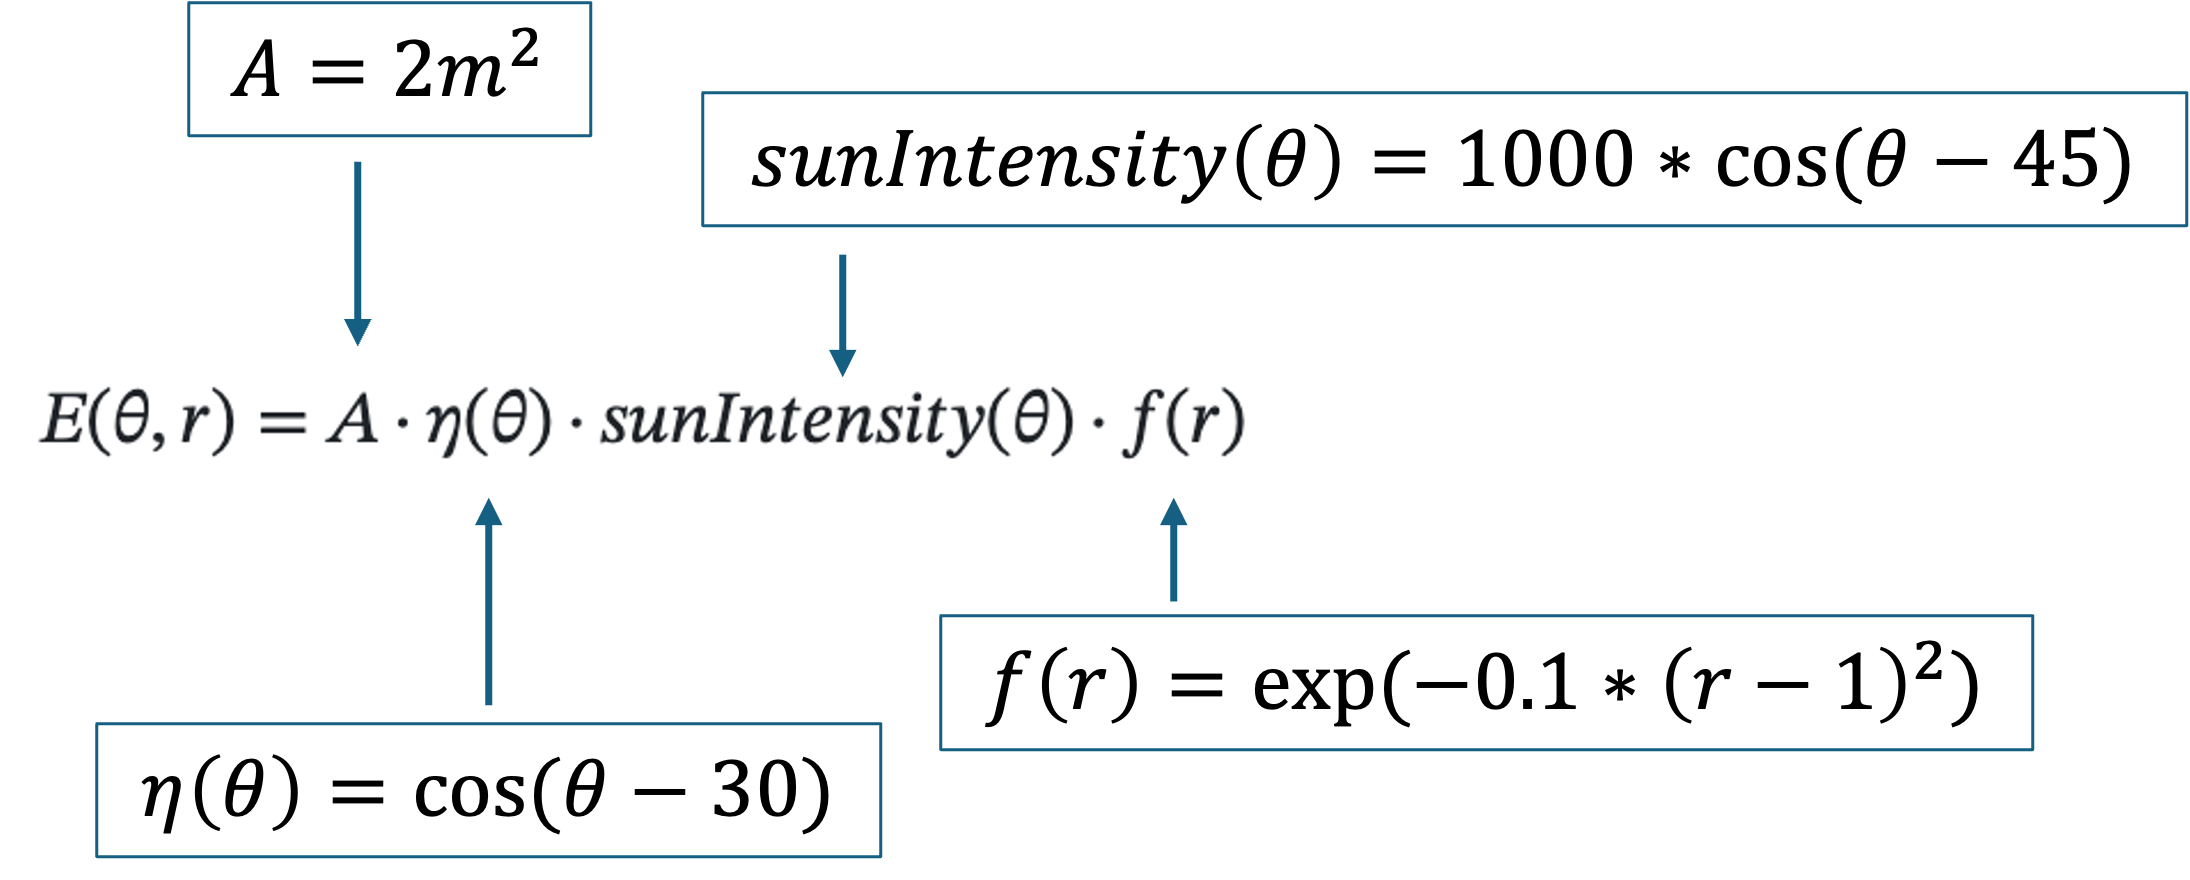 

In Model 2, "A" (the fixed panel area) also has a slider. However, unlike "`theta" `or "`r", "A" `has a positive linear proportionality to the Energy function therefore it does not need to be optimized. 

The purpose of giving "A" a slider was to calculate the **Total Energy Production** of an array of solar panels with the same Tilt Angle and Aspect Ratio in a given area.

Example Image of solar panel array:

Note: The solver uses radian values instead of degrees. Multiplying inside the cosine function with pi/180 convert the theta values from degrees to radians.

% Step 1: Define "A" (the fixed panel area); using the control panel create a slider from 0 to 20 with a step of 1  
        A = 10;

% Step 2: Define "nu" (the angle efficiency) in terms of the optimization variable theta 
    nu = cos((theta - 30)*pi/180);

% Step 3: Define "fr" (shape efficiency factor) in terms of the optimization variable r
    fr = exp(-0.1*(r - 1)^2);

% Step 4: Define "Sun_Intensity" (variation in sunlight) in terms of the optimization variable theta
    Sun_Intensity = 1000*cos((theta - 45)*pi/180);

% Step 5: Define the Objective Function "Energy" (Total Energy Output) in terms of "A", "nu", "Sun_Intensity" & "fr" which are in terms of "theta" and "r"
    Energy = A.*nu.*Sun_Intensity.*fr;

% Step 6: Create the Objective Function (Solar_Max.Objective)
    Solar_Max.Objective = Energy;

### Objective 3: Solve for Optimal Aspect Ratio and Tilt Angle 

In Model 1, for the **Initial Guess** the values were chosen because they were within the constraints. 

However, this does not work for Model 2. For the solve command, the optimization solvers searches for the nearest local Maximum based off the initial guess. As shown in the example surf plot, this method does not work when there are multiple local Maximums. 

Example surf plot using Model 1: 

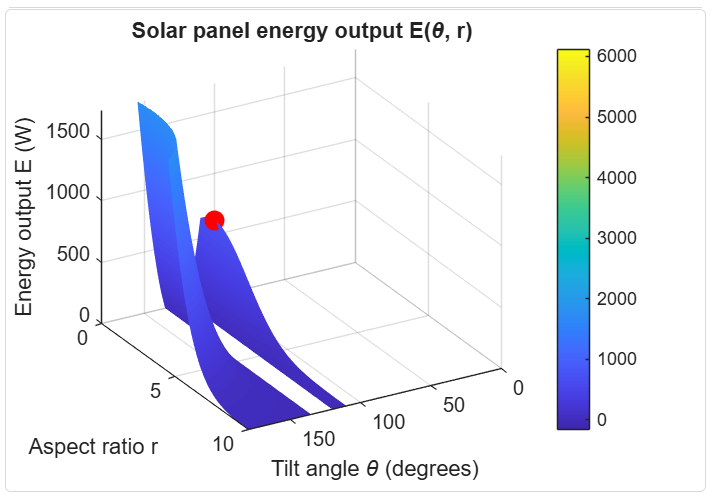

To solve this problem, the approach was to set up **Two Initial Guesses** around each peak and keep the larger value. To identify whether there is more than one peak use the surf plot built in Objective 4. 

Note: This section of code can be improved by increasing the amount of Initial Guesses to account for more local maximums when expanding and varying the constraints. 

% Step 1: Set up the first Initial Guess for "theta" & "r" and Store the results  
    % First Inital Guess (same as Model 1)
        initial_guess.theta = 45;
        initial_guess.r = 2;

    % Use the solve function to find the Tilt Angle and Aspect Ratio for 
    % the Maximum Energy Output of the first peak (maxE_1)  
        [solution, maxE_1] = solve(Solar_Max,initial_guess);


Solving problem using fmincon.

Local minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>



    % Store the results
        theta_1 = solution.theta;
        ratio_1 = solution.r;
        energy_1 = maxE_1;

% Step 2: Set up the second Initial Guess for "theta" & "r" and Store the results
     % Second Inital Guess (pick values outside the constraints of model 1
     % but within the absolute limits set for Model 2)  
         initial_guess.theta = 135;
         initial_guess.r = 7.5;
         
     % Use the solve function to find the Tilt Angle and Aspect Ratio for
     % the Maximum Energy Output of the second peak (maxE_2) 
         [solution, maxE_2] = solve(Solar_Max,initial_guess);


Solving problem using fmincon.

Local minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>



     % Store the results
         theta_2 = solution.theta;
         ratio_2 = solution.r;
         energy_2 = maxE_2;

% Step 3: Store the larger maxE value as "optimal_energy" using the max function 
    optimal_energy = max(maxE_1,maxE_2);
        
% Step 4: Create an if-else loop to store the optimal Tilt Angle and Aspect Ratio 
    % If the largest energy total ("MaxE") is "maxE_1" then the optimal
    % Tilt Angle and Aspect Ratio is "theta_1" and "ratio_1" 
        if (optimal_energy == maxE_1) 
            optimal_theta = theta_1;
            optimal_ratio = ratio_1;
    % Else, the largest energy total is "maxE_2" then the optimal Tilt Angle and 
    % Aspect Ratio is "theta_2" and "ratio_2"     
        
        elseif (optimal_energy == maxE_2)
            optimal_theta = theta_2;
            optimal_ratio = ratio_2;
        end

### Objective 4: Output the Results

**Plot E(θ, r)** to visualize the energy as a surface plot using `meshgrid` and [`surf`](https://www.mathworks.com/help/releases/R2026a/matlab/ref/surf.html). Plot the optimal tilt angle and aspect ratio, and corresponding energy output onto the grid; the absolute maximum of the surface plot should align with the optimal point. Finally, print the optimal tilt angle and aspect ratio, and the Maximum energy output.

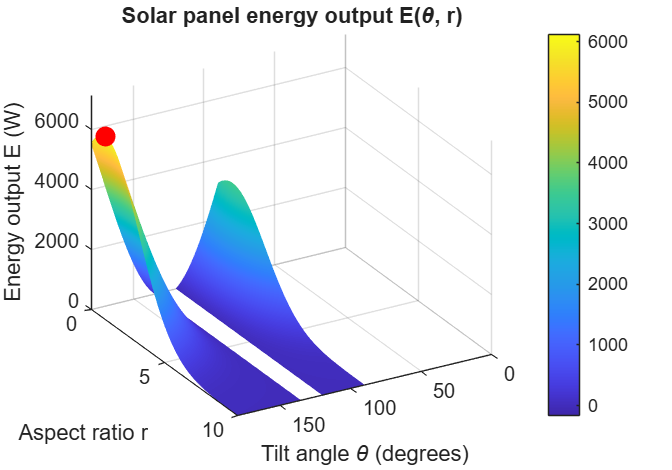

% Step 1: Create Grid Values for Tilt Angle and Aspect Ratio using meshgrid 

    % Set the lower bound to "theta_LowerB", the upper bound to
    % "theta_UpperB" and the steps to 1. 
        theta_values = theta_LowerB:1:theta_UpperB;
            % This allows the surf plot to show all energy
            % output values within the varying constraints
        
    % Set the lower bound to "r_LowerB", the upper bound to "r_UpperB" and
    % the steps to 0.1 
        r_values = r_LowerB:0.1:r_UpperB;

    % Create the meshgrid 
        [theta_grid, r_grid] = meshgrid(theta_values,r_values);

% Step 2: Generate energy grid values that are dependent on the "theta_grid" and "r_grid" 
    % Note: It's identical to 'Energy' the objective function
    energy_grid = A.*(cos((theta_grid-30).*pi/180)).*(1000.*cos((theta_grid-45).*pi/180)).*(exp(-0.1.*(r_grid-1).^2));

% Step 3: Use figure function to position the size and location of the plot 
    figure("Position",[100,100, 1000, 700]);

% Step 4: Create the Surface Plot using the surf function
        surf(theta_grid,r_grid,energy_grid);

    % Add shading that illustrate the gradual change in energy output using
    % shading and colorbar functions 
        shading interp;
        colorbar;

    % Set the x & y Axis limits for the plot to the absolute limits of each
    % constraint (these can be changed)
        xlim([0 180]);
        ylim([0 10]);

    % Set the z axis upper limit to 1000 plus more than the maximum energy
    % total ("optimal_energy") to always capture the value in the grid
        zlim([0 optimal_energy+1000]);

    % The view function can be changed to gain a better camera line of sight
    % of the surface plot  
        view(150, 30);

% Step 5: Label the plots
    xlabel("Tilt angle \theta (degrees)");
    ylabel("Aspect ratio r");
    zlabel("Energy output E (W)");
    title("Solar panel energy output E(\theta, r)");
    

% Step 6: Plot the optimal point on the surface plot
    hold on; 
    plot3(optimal_theta,optimal_ratio,optimal_energy,"r.","MarkerSize",30);
    hold off;


% Step 7: Print Results
    fprintf("Optimal Tilt Angle  : %.2f degrees\n", optimal_theta);

Optimal Tilt Angle  : 180.00 degrees


    fprintf("Optimal aspect ratio: %.2f\n", optimal_ratio);

Optimal aspect ratio: 1.00


    fprintf("Maximum energy      : %.2f W/m^2\n", optimal_energy);

Maximum energy      : 6123.72 W/m^2


### Interpretation of Results

    Through MATLAB's Optimization Toolbox™, Model 2 produced values consist of the maximum energy output. This can be seen through the optimal point plot aligning with the highest part of the surface plot representing the function $E\left(\theta ,r\right)$ in spite of varying constraints. In doing so, the model demonstrates the ability to find the optimal Tilt Angle and Aspect Ratio to deliver the maximum energy output for a solar panel in a variety of situations.

    However, Model 2 is limited because of it's fixed amount of initial guesses and the initial guess values. It cannot be applied efficiently to optimization problems outside of the given objective function and becomes less efficient the further the absolute limits are increased. Additionally, the objective function itself does not fully replicate all the variables that effect the energy output of a solar panel. 

    To improve on Model 2, a better algorithm is needed for estimating the initials guesses and repeating them across various parts of the grid.  Moreover, the objective function can be improved upon by adding a time variable or seasonal variable that provides better estimations of the maximum energy output from a solar panel. This provides great commercial applications. Lastly, now that the optimization problem is scalable the next venture is to design an app that can be utilized in industry for real-world applications. 